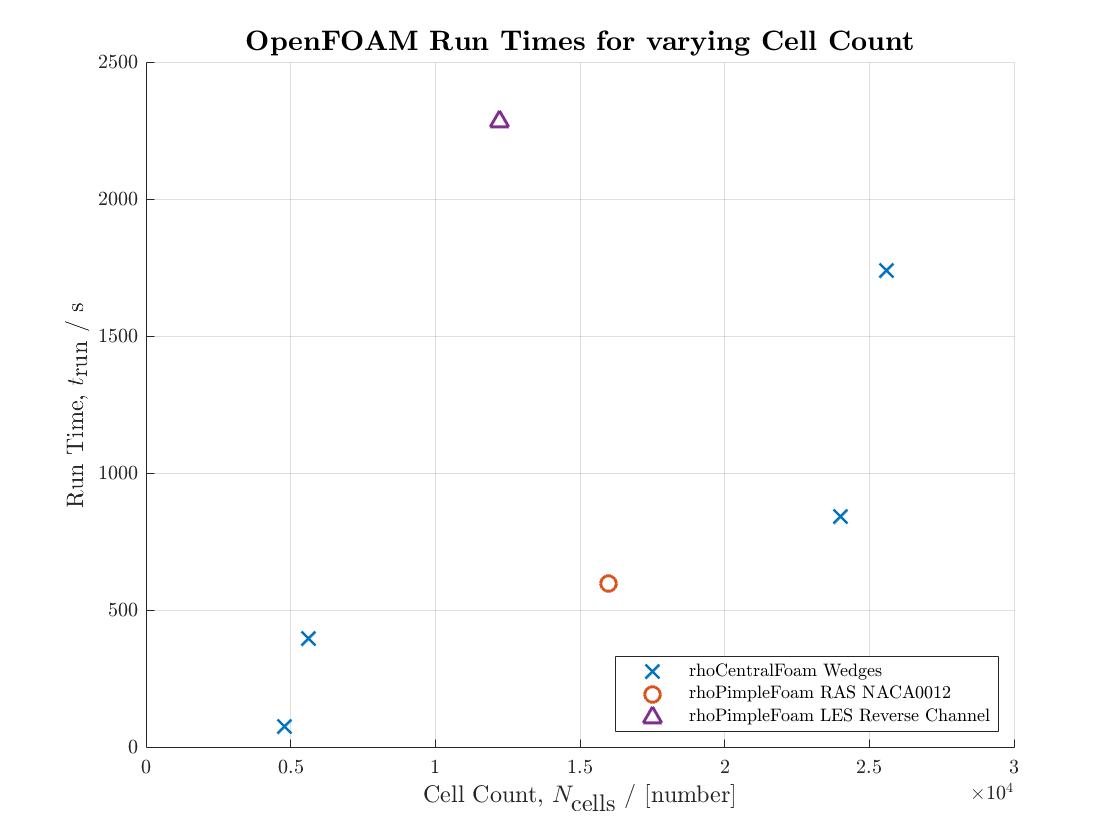

clear; clc; close all

width = 1.5 ; % Line thickness
lsize = 12 ; tsize = 14 ; legsize = 9 ; msize = 8 ; % Font size in plots, label, %title, %%legend
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultlegendInterpreter','latex');

% COLOURS - MaTLAB defaults
blue = [0 0.4470 0.7410]; orange = [0.8500 0.3250 0.0980]; yellow = [0.9290 0.6940 0.1250];
purple = [0.4940 0.1840 0.5560]; green = [0.4660 0.6740 0.1880]; 
lblue = [0.3010 0.7450 0.9330];	red = [0.6350 0.0780 0.1840]; black = [0 0 0];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Misc Cases
rhoCentralFoam=[4800, 24000,5600,25600;77,844,400,1741];
NACA0012_RAS_rhoPimpleFoam=[16000;600];
Reverse_LES_rhoPimpleFoam=[12225;2285];

figure        
plot(rhoCentralFoam(1,:),rhoCentralFoam(2,:),'x',"Color",blue,"MarkerSize",msize,'Linewidth',width)
hold on; grid on; box off
plot(NACA0012_RAS_rhoPimpleFoam(1,:),NACA0012_RAS_rhoPimpleFoam(2,:),'o',"Color",orange,"MarkerSize",msize,'Linewidth',width)
plot(Reverse_LES_rhoPimpleFoam(1,:),Reverse_LES_rhoPimpleFoam(2,:),'^',"Color",purple,"MarkerSize",msize,'Linewidth',width)
xlabel('Cell Count, $N_{\textrm{cells}}$ / [number]',"FontSize",lsize)
ylabel('Run Time, $t_{\textrm{run}}$ / s',"FontSize",lsize)
title('\textbf{OpenFOAM Run Times for varying Cell Count}','FontSize',tsize)
legend({'rhoCentralFoam Wedges','rhoPimpleFoam RAS NACA0012','rhoPimpleFoam LES Reverse Channel'},'Location','southeast','NumColumns',1,"FontSize",legsize)
hold off


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Diamond

ncells_diamond_correct=[5228,21408,52580,30444,21804,19224,3468,104120,31584,21408,14308];
trun_diamond_correct=[26,1371,5017.88,3054.45,2363.25,2153.98,429.69,15326.94,3891.62,2359.76,1385.27];
cd_diamond_corrected=[0.170414,0.170577,0.170723,0.170556,0.170523,0.170822,0.170684,0.169459,0.170698,0.170523,0.170523]

cd_diamond_corrected =     0.1704    0.1706    0.1707    0.1706    0.1705    0.1708    0.1707    0.1695    0.1707    0.1705    0.1705


cl_diamond_corrected=[0.424,0.424,0.423757,0.423366,0.423457,0.424073,0.424699,0.413042,0.423369,0.423457,0.423937]

cl_diamond_corrected =     0.4240    0.4240    0.4238    0.4234    0.4235    0.4241    0.4247    0.4130    0.4234    0.4235    0.4239


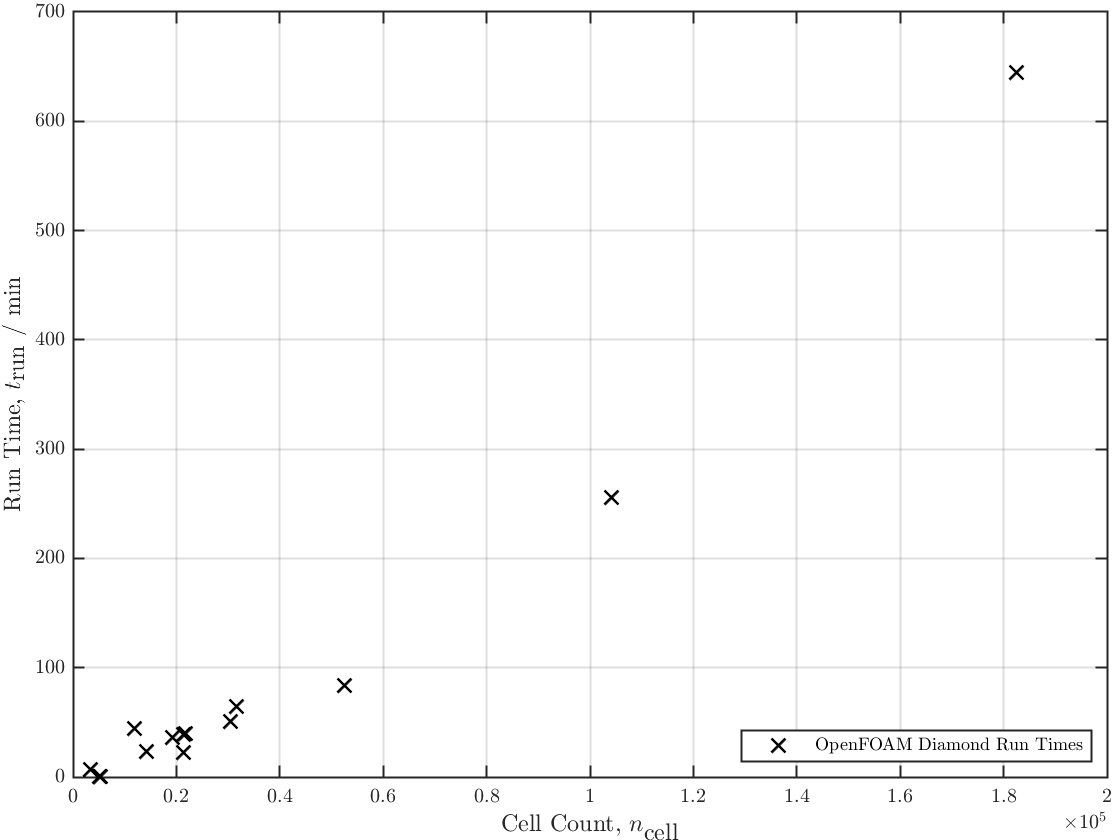


ncells_diamond_unadjusted=[11904,5208,5208,182436];
trun_diamond_unadjusted=[2650,32.75,51.49,38668.3];

figure        
plot(ncells_diamond_correct,trun_diamond_correct./60,'x',"Color",black,"MarkerSize",msize,'Linewidth',width)
hold on; grid on; box off
plot(ncells_diamond_unadjusted,trun_diamond_unadjusted./60,'x',"Color",black,"MarkerSize",msize,'Linewidth',width)
xlabel('Cell Count, $n_{\textrm{cell}}$',"FontSize",lsize)
ylabel('Run Time, $t_{\textrm{run}}$ / $\textrm{min}$',"FontSize",lsize)
%title('\textbf{OpenFOAM Run Times for varying Cell Count}','FontSize',tsize)
legend({'OpenFOAM Diamond Run Times'},'Location','southeast','NumColumns',1,"FontSize",legsize)
grid on; box on; hold on
%title(['\textbf{Lines of Constant Lift,} $C_L\times\textrm{Ma}^2$ \textbf{, based on ref. points}'],'FontSize',tsize)
hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;
saveas(gcf,'diamond_runtime.png')

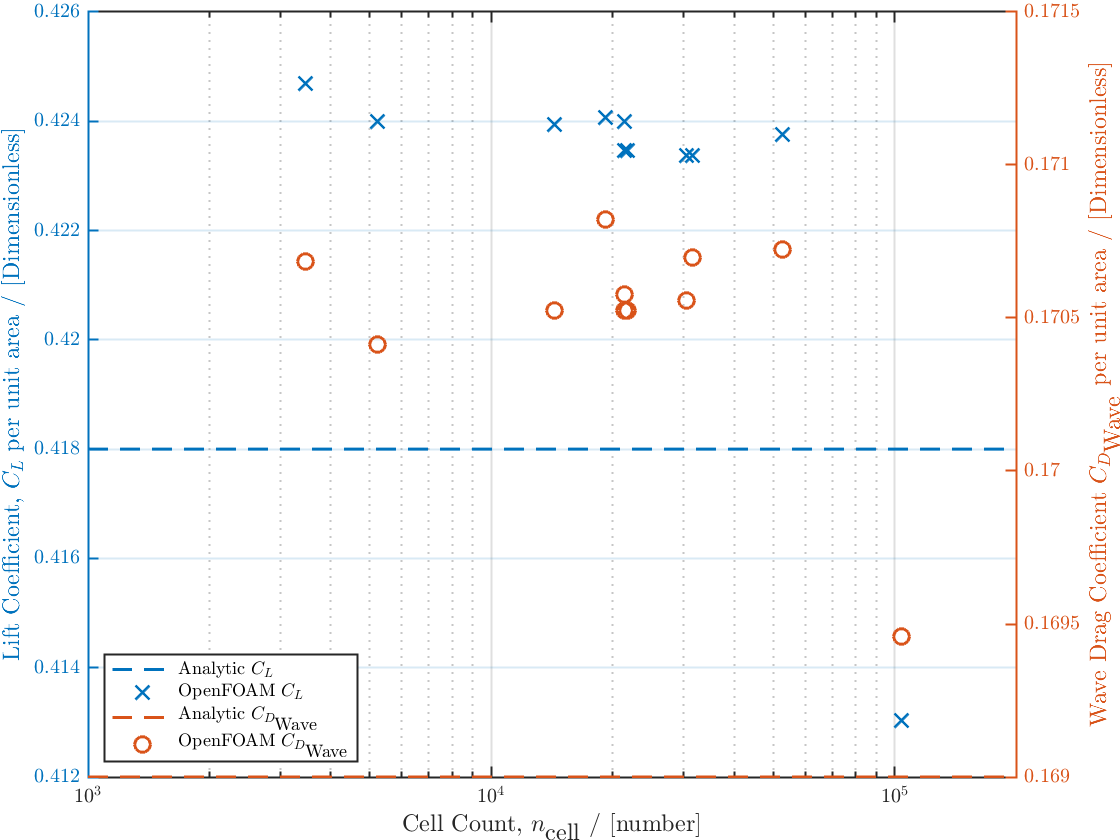


% Foam_basesizes = [0.001,0.01,0.1,1];
% Foam_ncells = [10000,1000,100,10];
% Foam_basesizes_cl = [0.010,0.013,0.12,1];
% Foam_basesizes_cd = [0.15,0.18,0.23,0.51];
Analytic_ncells = [0,1000,200000];
% Analytic_basesizes = [0.001,1];
Analytic_cl = [0.418,0.418,0.418];
Analytic_cd = [0.169,0.169,0.169];

% figure
% grid on
% yyaxis left
% semilogx(Analytic_basesizes,Analytic_cl,'--','LineWidth',width,"Color",blue)
% hold on
% semilogx(Foam_basesizes,Foam_basesizes_cl,'x-','LineWidth',width,"Color",blue)
% hold on
% title({'\textbf{Effect of Mesh Factor on Lift and Drag Coefficients} ($C_L$,$C_{D_{\textrm{Wave}}}$)','\textbf{OpenFOAM Sim., $10^\circ$ Half-Wedge Diamond Airfoil:} Ma=3, $\alpha = 15^\circ$'},"FontSize",tsize)
% %grid on
% %xlim([0.0 0.5])
% %ylim([0.46 0.51])
% xlabel('Base Size, BS / c',"FontSize",lsize)
% ylabel('Lift Coefficient ($C_L$) / [Dimensionless]',"FontSize",lsize)
% yyaxis right
% semilogx(Analytic_basesizes,Analytic_cd,'--','LineWidth',width,"Color",orange)
% hold on
% semilogx(Foam_basesizes,Foam_basesizes_cd,'o-','LineWidth',width,"Color",orange)
% ylim([0 1])
% ylabel('Drag Coefficient ($C_{D_{\textrm{Wave}}}$) / [Dimensionless]',"FontSize",lsize)
% legend({'Analytic $C_L$','OpenFOAM $C_L$','Analytic $C_{D_{\textrm{Wave}}}$','OpenFOAM $C_{D_{\textrm{Wave}}}$'},'Location','northeast','NumColumns',1,"FontSize",legsize)
% set ( gca, 'xdir', 'reverse' )
% hold on
% box off
% hold off

figure
grid on
yyaxis left
semilogx(Analytic_ncells,Analytic_cl,'--','LineWidth',width,"Color",blue)
hold on
semilogx(ncells_diamond_correct,cl_diamond_corrected,'x','LineWidth',width,"Color",blue,"MarkerSize",msize)
hold on
%title({'\textbf{Effect of Cell Count on Lift and Drag Coefficients} ($C_L$,$C_{D_{\textrm{Wave}}}$)','\textbf{OpenFOAM Sim., $10^\circ$ Half-Wedge Diamond Airfoil:} Ma=3, $\alpha = 15^\circ$'},"FontSize",tsize)
%grid on
%xlim([0.0 0.5])
%ylim([0.46 0.51])
xlabel('Cell Count, $n_{\textrm{cell}}$ / [number]',"FontSize",lsize)
ylabel('Lift Coefficient, $C_L$ per unit area / [Dimensionless]',"FontSize",lsize)
yyaxis right
semilogx(Analytic_ncells,Analytic_cd,'--','LineWidth',width,"Color",orange)
hold on
semilogx(ncells_diamond_correct,cd_diamond_corrected,'o','LineWidth',width,"Color",orange,"MarkerSize",msize)
%ylim([0 1])
ylabel('Wave Drag Coefficient $C_{D_{\textrm{Wave}}}$ per unit area / [Dimensionless]',"FontSize",lsize)
legend({'Analytic $C_L$','OpenFOAM $C_L$','Analytic $C_{D_{\textrm{Wave}}}$',...
    'OpenFOAM $C_{D_{\textrm{Wave}}}$'},'Location','southwest',...
    'NumColumns',1,"FontSize",legsize)
%set ( gca, 'xdir', 'reverse' )
grid on; box on; hold on
hold off
InSet = get(gca, 'TightInset');
set(gca, 'Position', [InSet(1:2), 1-InSet(1)-InSet(3), 1-InSet(2)-InSet(4)]);
H=gca; H.LineWidth=1;
saveas(gcf,'diamond_convergence.png')


% figure
% plot(iters,Star2Deg_Cd,'color',[1 0 0],'LineWidth',1.5)
% hold on
% plot(iters,Star2Deg_Cl,'color',[0 1 0],'LineWidth',1.5)
% hold on
% xlim([0 1000])
% %ylim([-1 1.2])
% grid on
% title({'2D STAR-CCM+ Histories for Lift and Drag Coefficients (C_L&C_D)','DF102-PT Aerofoil: \alpha=2^\circ, Re=300900, Ma=0.3'})
% xlabel('Iteration Count')
% ylabel('Coefficient Monitor / [Dimensionless]')
% legend({'Drag Monitor (C_D)','Lift Monitor (C_L)'},'Location','northeast','NumColumns',1)
% %
% grid on
% %
% box off
% hold off

% figure
% semilogy(iters, star2degres(:,2),'Color',[1 0 0],'LineWidth',1.5)
% hold on
% semilogy(iters, star2degres(:,3),'Color',[0 1 0],'LineWidth',1.5)
% hold on
% semilogy(iters, star2degres(:,4),'Color',[0 0 1],'LineWidth',1.5)
% hold on
% semilogy(iters, star2degres(:,5),'Color',[0.9290 0.6940 0.1250],'LineWidth',1.5)
% hold on
% semilogy(iters, star2degres(:,6),'Color',[1 0 1],'LineWidth',1.5)
% hold on
% semilogy(iters, star2degres(:,7),'Color',[0 1 1],'LineWidth',1.5)
% hold on
% xlim([0 1000])
% ylim([10E-10 1])
% grid on
% title({'STAR-CCM+ Residuals for DF102-PT Aerofoil: \alpha=2^\circ, Re=300900, Ma=0.3'})
% xlabel('Iteration Count')
% ylabel('Residual')
% legend({'Continuity','X-Momentum','Y-Momentum','SDR','TKE','Energy'},'Location','northeast','NumColumns',1)
% %
% grid on
% %
% box off
% hold off   

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Busemann


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%